# Ejercicio 2. Procesado de Imágenes

**Tarea propuesta: eliminación de un ruido sinusoidal en una imagen.**

**a)** Carga la imagen “xray.jpg”, añádele un ruido sinusoidal y representa la imagen resultante y su Transformada de Fourier 2D.

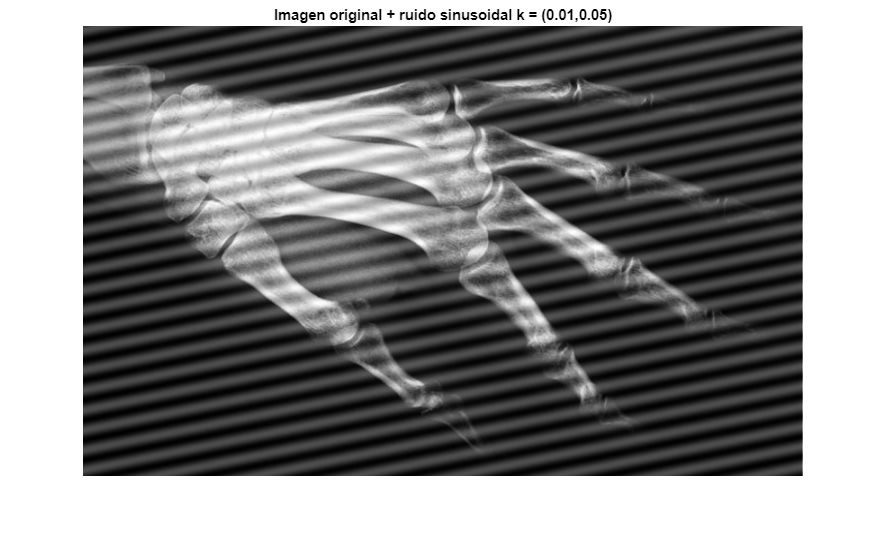

clear all
close all

img_rgb = imread('xray.jpg');
x=rgb2gray(img_rgb);
[size_H,size_W] = size(x);
u_axis = 1:size_W;
v_axis = 1:size_H;
[uu,vv] = meshgrid(u_axis,v_axis);
noise = 50*sin(2*pi*(0.01*uu+0.05*vv));
x_mod = (double(x)+noise);

figure()
imshow(x_mod,[])
title("Imagen original + ruido sinusoidal k = (0.01,0.05)")

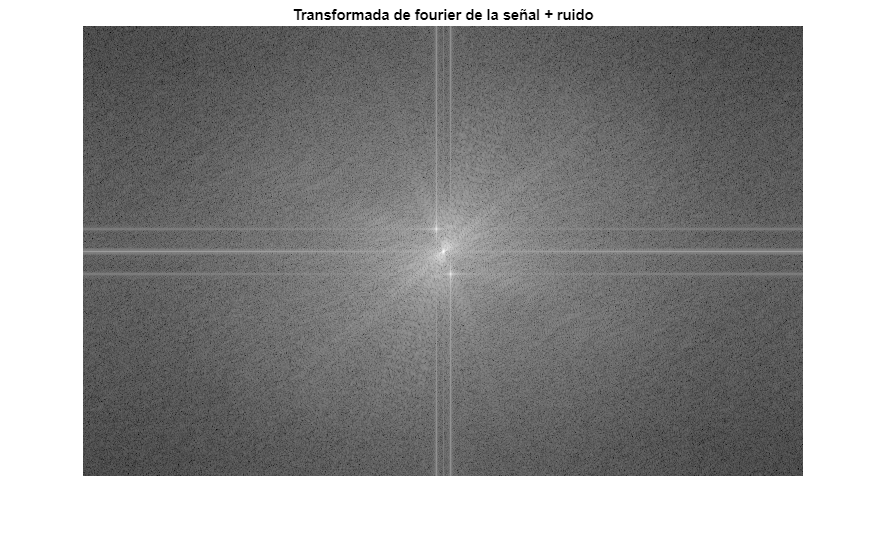

Xmod = fftshift(fft2(x_mod));
figure()
imshow(log10(1+abs(Xmod).^2),[])
title("Transformada de fourier de la señal + ruido")

[x_lim, y_lim] = size(Xmod)

x_lim = 450

y_lim = 720

`Al aplicar un ruido sinusoidal con una frecuencia bien definida, en la transformada de fourier aparecen unos picos muy marcados próximos al centro del espectro. Estos destellos derivados del ruido pueden eliminarse aplicando un filtro en el espacio reciproco para recuperar una imagen lo más similar posible a la original.`

**b)** Diseña la respuesta en frecuencia deseada del filtro apropiado para eliminar el ruido sinusoidal y obtén un filtro que se aproxime al deseado. Representa tanto la respuesta en frecuencia deseada, como la finalmente obtenida. Nota: el comando fsamp2 permite obtener los coeficientes h(n) de un filtro a partir de una respuesta en frecuencia deseada (Hd(w)).

`Para obtener la respuesta en frec del filtro hacemos la ft del kernel. Al hacer la ft aparecen dos destellos diagonales indeseados. El filtro debe eliminar tansolo los dos destellos que están en diagonal con el centro, pero el centro debe permanecer invariante.`

`Lo que haremos será aplicar dos filtros pasa alta desplazados. Cada uno de ellos deberá centrarse en cada uno de los destellos.`

N = 100;
Hd = ones(N);
Hd_1 = ones(N);
Hd_2 = ones(N);

[u,v] = freqspace(N); % equiespaciado entre -1 y 1 equiespaciados con N valores.
[uu,vv] = meshgrid(u,v);

`Se diseña el espacio en que idealmente se van a eliminar todas las componentes en frecuencia de la imagen ruidosa.`

`En primera instancia se calculan los centros. Deben localizarse aproximadamente sobre los destellos, como Duu y Dvv están definidos entre -1 y 1 hay que hacer el reescalado. El tamaño del espectro es de 720x450 píxeles. Los destellos aparecen localizados en (353,206) y (368,249), que respecto al centro (360,225) están a (-7,-19) y (8,24). Reescalando esto a un espectro entre -1 y 1 se llega a unos centros en: (0.0208, 0.1027).`

`A continuación ha de definirse por tanteo el radio de la zona a suprimir. Con una serie de iteraciones se llega a que un valor razonable para el radio de acción es de 0.0009`

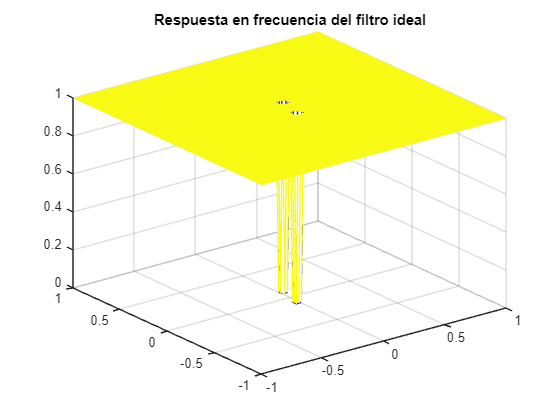

Duv_1 = (uu+0.0208).^2 + (vv+0.1027).^2;
Duv_2 = (uu-0.0208).^2 + (vv-0.1027).^2;

Hd_1(Duv_1<0.0009) = 0;
Hd_2(Duv_2<0.0009) = 0;
Hd = (Hd_1+Hd_2)-1;

figure()
mesh(uu,vv,abs(Hd))
title("Respuesta en frecuencia del filtro ideal")

`Ahora debemos diseñar el kernel que será el que convolucione con la imagen. Este no puede ser el ideal. A partir del comando fsapm2() Matlab diseñará el kernel que más se aproxime a lo que se ha diseñado idealmente en Hd.`

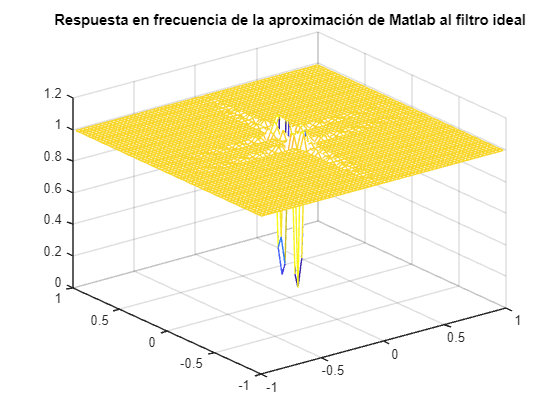

h = fsamp2(Hd);
[H,uw,vw] = freqz2(h);
[uu2,vv2] = meshgrid(uw,vw);
figure()
mesh(uu2,vv2,abs(H))
title("Respuesta en frecuencia de la aproximación de Matlab al filtro ideal")

`Si se compara el filtro teórico con la aproximación de Matlab hay grandes diferencias. La aproximación contienen significativos rizados en las zonas de cambio. Además no alcanza totalmente el 0 practicamente en ningún momento. Por esto, anteriormente se ha descrito el proceso de obtención de la superficie a eliminar como iterativo. Este ajuste depende tremendamente de como de buena sea la aproximación de Matlab.`

**c)** Filtra la imagen con el filtro obtenido en el apartado anterior y representa la imagen resultante y su Transformada de Fourier 2D.

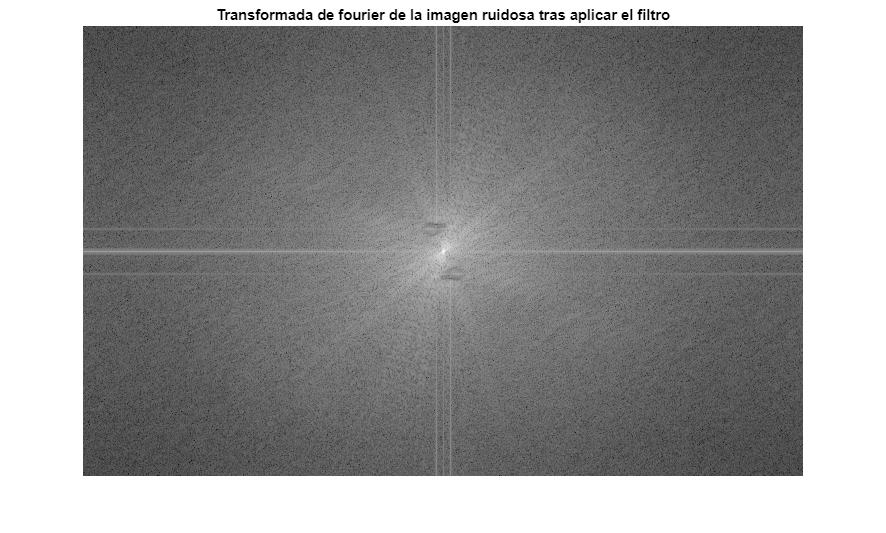

Xmod = fftshift(fft2(x_mod));
y = filter2(h,x_mod);
Ymod = fftshift(fft2(y));
figure()
imshow(log10(1+abs(Ymod).^2),[])
title("Transformada de fourier de la imagen ruidosa tras aplicar el filtro")

`Tras aplicar el filtro han desaparecido los destellos derivados de la señal sinusoidal ruidosa que se había aplicado. De nuevo el resultado no es ideal. Pueden observarse surgos derivados de haberse aplicado los filtros. Estos filtros no son puntuales, afectan a un área siempre mayor de la deseada. De ahí que el diseño deba ser lo más óptimo posible para que la reconstrucción sea razonablemente buena.`

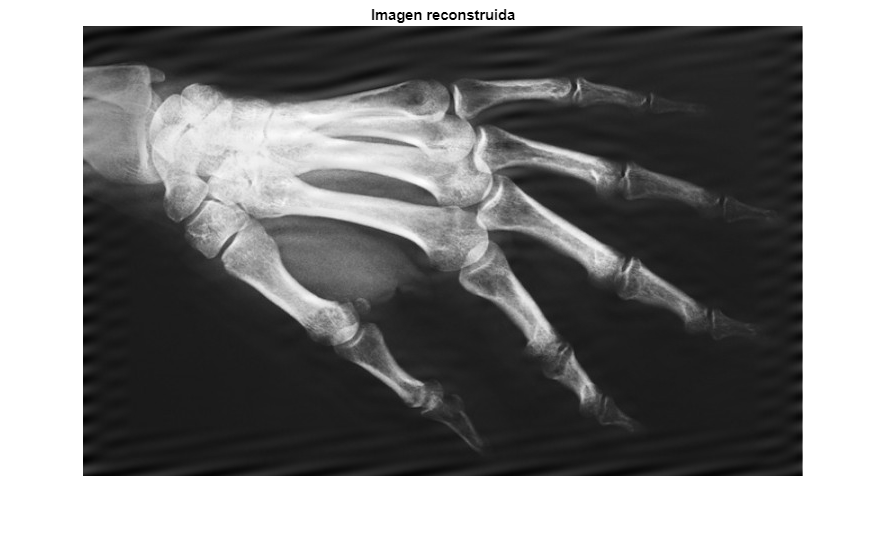

figure()
imshow(y,[])
title("Imagen reconstruida")

`Finalmente se obtiene una señal en la que gran parte del ruido ha desaparecido. Pueden verse con claridad todos los detalles de la mano que antes estaban tapados por el ruido.`